# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 9: Descripcion y control en espacio de estado II

#### **Tarea 1: Descripcion en espacio de estado**

Se desea realizar el control servo por asignacion de polos para un sistema definido por:


$$A=\left[\matrix {0 & 1 \cr -10 & -11}\right] \qquad B=\left[\matrix {0 \cr 2}\right] \qquad C=\left[\matrix {1 & 0}\right] \qquad D=\left[\matrix {0}\right]$$


**a)** Obtener la representacion en espacio de estado y convertir el sistema a funcion de transferencia determinando el tipo del sistema. ¿Se puede determinar el tipo del sistema desde la representacion en el espacio de estado?

% Tu código aquí
clear all 
sys1 = ss([0 1;-10 -11],[0;2],[1 0],0)

sys1 =
 
  A = 
        x1   x2
   x1    0    1
   x2  -10  -11
 
  B = 
       u1
   x1   0
   x2   2
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


G1 = tf(sys1)

G1 =
 
         2
  ---------------
  s^2 + 11 s + 10
 
Continuous-time transfer function.
Model Properties


polos_ba = eig(sys1.A) %hay algo mal q no entiendo

polos_ba =     -1
   -10


`Resultado esperado:`

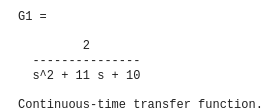

**b)** En el caso de un sistema tipo 0 (sin integrador), añadir un integrador y calcular el vector de ganancias de control extendido definido por $\textbf{\hat{K}}=\left[\matrix {\textbf{K} : k_I} \right]$para que el sistema exhiba un comportamiento dinamico con respuesta temponral crticamente amortiguada, tiempo de establiecmiento inferior a 0.8 segundos y error nulo en estado estacionario.

% Tu código aquí
% Sistema tipo 0: control servo con integrador
Mc = ctrb(sys1)

Mc =      0     2
     2   -22


rank(Mc)

ans = 2

Mo = obsv(sys1);
rank(Mo)

ans = 2

A_hat =[sys1.A zeros(2,1);-sys1.C 0]

A_hat =      0     1     0
   -10   -11     0
    -1     0     0


B_hat = [sys1.B;0]

B_hat =      0
     2
     0


C_hat = [sys1.C,0]

C_hat =      1     0     0


D_hat = [sys1.D]

D_hat = 0

ts = 0.8;
sigma = 4/ts;
polos_bc = [-sigma -sigma -5*sigma]

polos_bc =     -5    -5   -25


K_hat = acker(A_hat, B_hat,polos_bc)

K_hat =   132.5000   12.0000 -312.5000


`Resultado esperado:`

**c)** Comprobar el diseño en Matlab mediante la simulacion del esquema de control diseñado para una entrada escalon unitario y mostrando la evolucion temporal del vector de estado completo, a partir de la ecuacion de estado extendida. 


$$\left[\matrix {\dot{x}(t) \cr \dot{\zeta}} \right]=\left[\matrix{\textbf{A} & \textbf{0} \cr -\textbf{C} & 0} \right] \left[\matrix{x(t) \cr \zeta(t)} \right] + \left[ \matrix{\textbf{B} \cr 0}\right] u(t)+\left[\matrix{\textbf{0} \cr 1} \right] r(t)
\\
\\
u(t)=-\textbf{K}x(t)+k_I \zeta(t)$$


% Tu código aquí
sys1_bc = ss(A_hat-B_hat*K_hat,[0;0;1],C_hat,D_hat)

sys1_bc =
 
  A = 
         x1    x2    x3
   x1     0     1     0
   x2  -275   -35   625
   x3    -1     0     0
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


[y,t,x] = step(sys1_bc)

y =          0
    0.0001
    0.0006
    0.0017
    0.0038
    0.0069
    0.0111
    0.0165
    0.0229
    0.0304


t =          0
    0.0092
    0.0184
    0.0276
    0.0368
    0.0461
    0.0553
    0.0645
    0.0737
    0.0829


x =          0         0         0
    0.0001    0.0238    0.0092
    0.0006    0.0858    0.0184
    0.0017    0.1743    0.0276
    0.0038    0.2800    0.0368
    0.0069    0.3961    0.0460
    0.0111    0.5172    0.0551
    0.0165    0.6394    0.0642
    0.0229    0.7597    0.0732
    0.0304    0.8758    0.0822


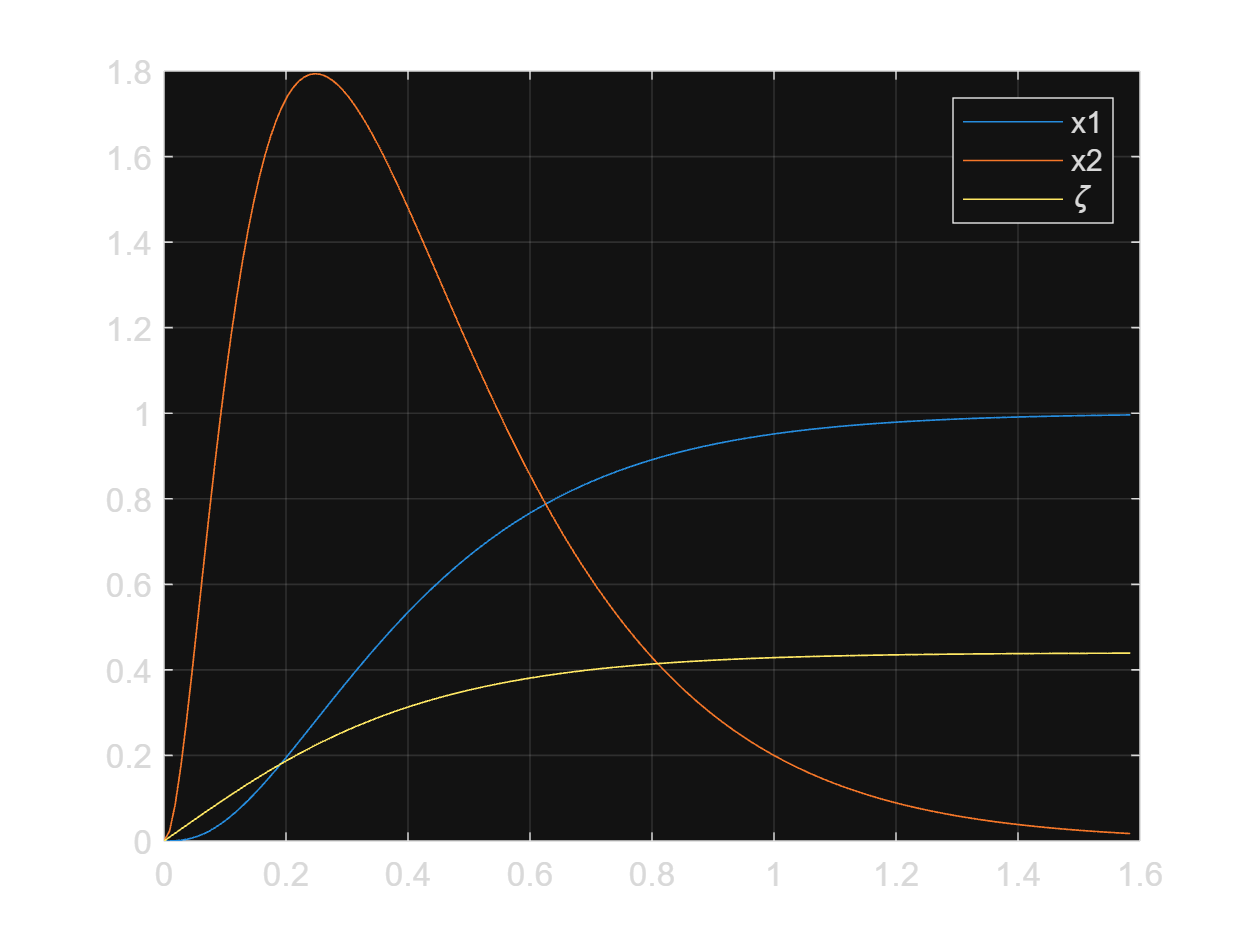

figure;plot(t,x);grid;legend('x1','x2','\zeta')

`Resultado esperado:`

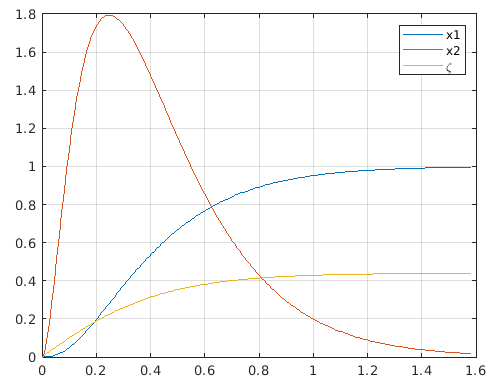

#### Tarea 2: Control en espacio de estado

La funcion de transferencia de un motor esta dada por $G(s)=\frac{\theta(s)}{V(s)}=\frac{1}{s(s+2)}$, con $\theta(t)$ y $v(t)$ son la posicion angular y la tension de entrada respectivamente.

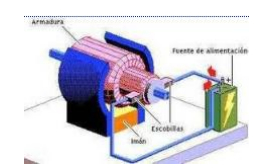

**a)** Obtener la representacion en espacio de estado para un vector de estado con compoentes posicion angular y velocidad angular, siendo la salida la posicion angular.

obtengo las matrices del systema y las meto directo a matlab

% Tu código aquí
sys2 = ss([0 1;0 -2],[0;1],[1 0],0)

sys2 =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -2
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


`Resultado esperado:`

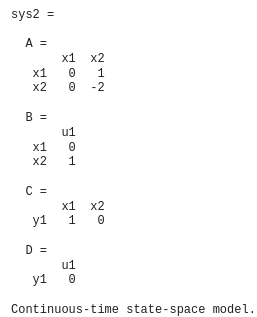

**b)** Se desea que el motor sea controlado en espacio de estado para que exhiba un comportamiento de segundo orden especificado por un par de polos deseados en $\mu_1,\mu_2=-2\pm5j$. Hallar el vector de ganacias ***K*** a partir de la formula de Ackerman.

% Tu código aquí
Mc = ctrb(sys2)

Mc =      0     1
     1    -2


rank(Mc)

ans = 2

Mo = obsv(sys2)

Mo =      1     0
     0     1


rank(Mo)

ans = 2

polos = [-2+5*1j -2-5*1j]

polos =   -2.0000 + 5.0000i  -2.0000 - 5.0000i



K = acker(sys2.A,sys2.B,polos)

K =     29     2


`Resultado esperado:`

**c)** Diseñar un observador de orden completo para estimar el estado, con una dinamica definida por $\mu_{1o},\mu_{2o}=-10$ y calcular la matriz de ganancias del observador $\textbf{K}_e$ a partir de la formula de Ackermann.

% Tu código aquí
% Observador %Como la matriz es obervable puedo hacer esto
polos_obs = [-10 -10]

polos_obs =    -10   -10


Ke = acker(sys2.A',sys2.B',polos_obs)

Error using acker
The A and B matrices must have the same number of rows.

`Resultado esperado:`

**d)** Utilizar ambas ganancias $\textbf{K}$ y $\textbf{K}_e$ para construir el control servo por asignacion de polos en Simulink y obtener la respuesta del sistema partiendo de condiciones iniciales $\theta(0)=1$y $\dot{\theta}(0)=0.1$, usando la ecuacion de estado del observador:


$$\textbf{\dot{\tilde{x}}(t)}=\textbf{A} \textbf{\tilde{x}(t)}+\textbf{B} u(t)+\textbf{K}_e(y(t)-\tilde{y}(t)) \rightarrow \textbf{\dot{\tilde{x}}(t)}=(\textbf{A}-\textbf{K}_e\textbf{C}) \textbf{\tilde{x}(t)}+\textbf{B} u(t)+\textbf{K}_e y(t)$$


Analizar la evolucion temporal del error de estimacion.

% Pega una captura de tu modelo simulink aqui


`Resultado esperado:`